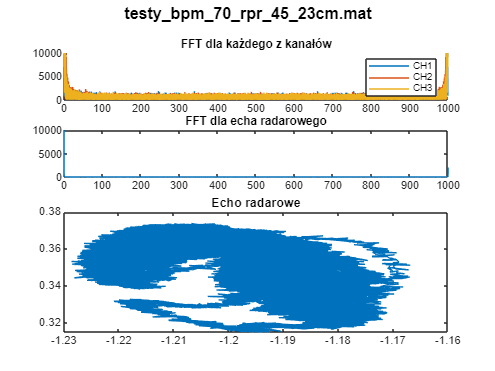

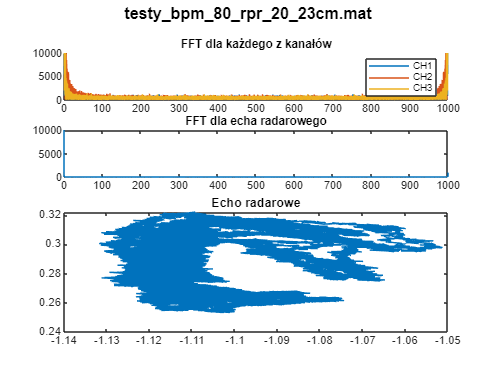

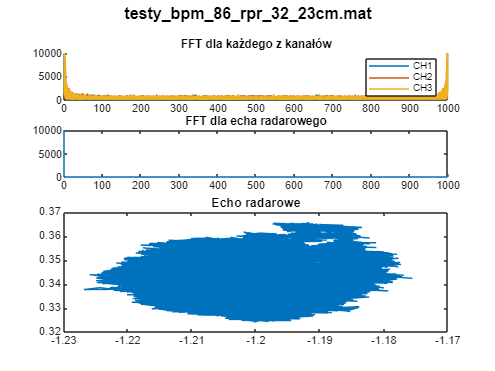

folderName = '23_03_2025_twarz';
fileList = dir(fullfile(folderName, '*.mat'));
if isempty(fileList)
    disp('No .mat files found in the selected folder.');
    return;
end
dataStruct = struct('name', {}, 'fch1', {}, 'fch2', {}, 'fch3', {}, 'fch4', {}, 'fIcurrent', {}, 'f', {});

% Loop over each file in the folder
for k = 1:length(fileList)
    % Construct the full file path
    filePath = fullfile(folderName, fileList(k).name);
    dataStruct(k).name = fileList(k).name;
    
    % Load the data from the file (assumed to be a .mat file)
    fileData = load(filePath);
    
    fsampling = 1000;
    fch1_clean = fft(fileData.ch1);
    fch2_clean = fft(fileData.ch2);
    fch3_clean = fft(fileData.ch3);
    fch4_clean = fft(fileData.ch4);
    radar_echo_data = radar_echo(fileData.ch1, fileData.ch2, fileData.ch3, fileData.ch4);
    fch5_clean = fft(radar_echo_data);
    
    %f = linspace(-fsampling/2, fsampling/2, length(fch1_clean));
    f = linspace(0, fsampling, length(fch1_clean));

    dataStruct(k).fch1 = fch1_clean;
    dataStruct(k).fch2 = fch2_clean;
    dataStruct(k).fch3 = fch3_clean;
    dataStruct(k).fch4 = fch4_clean;
    dataStruct(k).fIcurrent = fch5_clean;
    dataStruct(k).f = f;

    % Create a new figure for the current file's data
    figure; 
    subplot(4,1,1);
    hold on;
    plot(f, abs(fch1_clean));
    plot(f, abs(fch2_clean));
    plot(f, abs(fch3_clean));
    %plot(f, abs(fch4_clean));
    legend(["CH1", "CH2", "CH3"]);
    hold off;
    title("FFT dla każdego z kanałów");
    ylim([0, 10000]);
    subplot(4,1,2);
    plot(f, abs(fch5_clean));
    title("FFT dla echa radarowego");
    ylim([0, 10000]);
    subplot(2,1,2);
    plot(real(radar_echo_data), imag(radar_echo_data));
    title("Echo radarowe");
    sgtitle(fileList(k).name, 'Interpreter', 'none', 'FontSize', 12, 'FontWeight', 'bold');
end


function I = radar_echo(ch1, ch2, ch3, ch4)
    P4 = (ch3 - 14970.8) / 369.597;
    P3 = (ch2 - 14970.8) / 369.597;
    P2 = (ch1 - 14970.8) / 369.597;
    Pref = (ch4 - 14970.8) / 369.597;
    P4norm = P4-Pref;
    P3norm = P3-Pref;
    P2norm = P2-Pref;
    P4norm = 10.^(P4norm/10);
    P3norm = 10.^(P3norm/10);
    P2norm = 10.^(P2norm/10);
    I = -P2norm+0.5*P3norm+0.5*P4norm+1i*sqrt(3)/2*(-P3norm+P4norm);
end

fft_no_fan = dataStruct(find(strcmp({dataStruct.name}, 'testy_no_fan_upfront_55cm.mat'), 1)).fIcurrent;

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.

fft_fan = dataStruct(find(strcmp({dataStruct.name}, 'testy_fan_upfront_55cm.mat'), 1)).fIcurrent;
final_fft = abs(fft_fan) - abs(fft_no_fan);
figure;
subplot(3,1,1);
plot(f, abs(final_fft));
ylim([0, 10000]);
subplot(3,1,2);
plot(f, abs(fft_fan));
ylim([0, 10000]);
subplot(3,1,3);
plot(f, abs(fft_no_fan));
ylim([0, 10000]);